clear
clc

Se va a importar la base de datos

% Se escoje la base de datos que se quiere analizar 
% data = importdata("sec1.mat");
data = importdata("sec8.mat"); 
% data = importdata("sec9.mat");

Numero de puntos por anillo

puntos = 20;                             

Definicion de las variables para la construcción de los parches de Bézier 

Matriz_puntos_control = PuntosControl(data, puntos);

s = size(Matriz_puntos_control)

s =     61     3     7


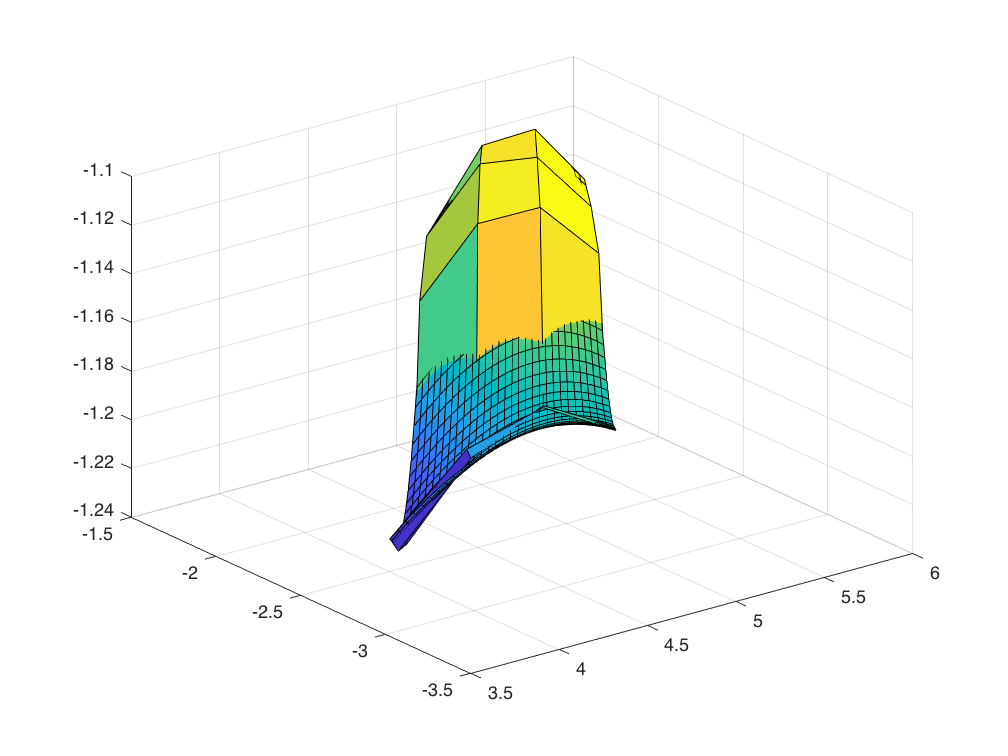

ans =     28     3


Upca =     0.7073   -0.7039   -0.0649
    0.7055    0.7087    0.0028
    0.0441   -0.0478    0.9979


score =     0.9326    0.3265   -0.0147
    0.8687    0.3305   -0.0107
    0.8038    0.3345   -0.0076
    0.7379    0.3385   -0.0052
    0.6710    0.3426   -0.0038
    0.6033    0.3467   -0.0031
    0.5348    0.3507   -0.0032
    0.4657    0.3548   -0.0040
    0.3962    0.3589   -0.0054
    0.3265    0.3631   -0.0072


latent =     0.2767
    0.0548
    0.0001


tsquared =     7.8077
    6.1659
    5.0932
    4.4028
    3.9471
    3.6304
    3.4094
    3.2833
    3.2786
    3.4322


explained =    83.4428
   16.5331
    0.0241


mu =     4.7080   -2.4602   -1.1609


punto_medio_origen =     0.0020    0.0025   -0.0001


matriz_rotacion =     0.7073   -0.7039   -0.0649
    0.7055    0.7087    0.0028
    0.0441   -0.0478    0.9979


determinanate_matriz_rotacion = 1.0000

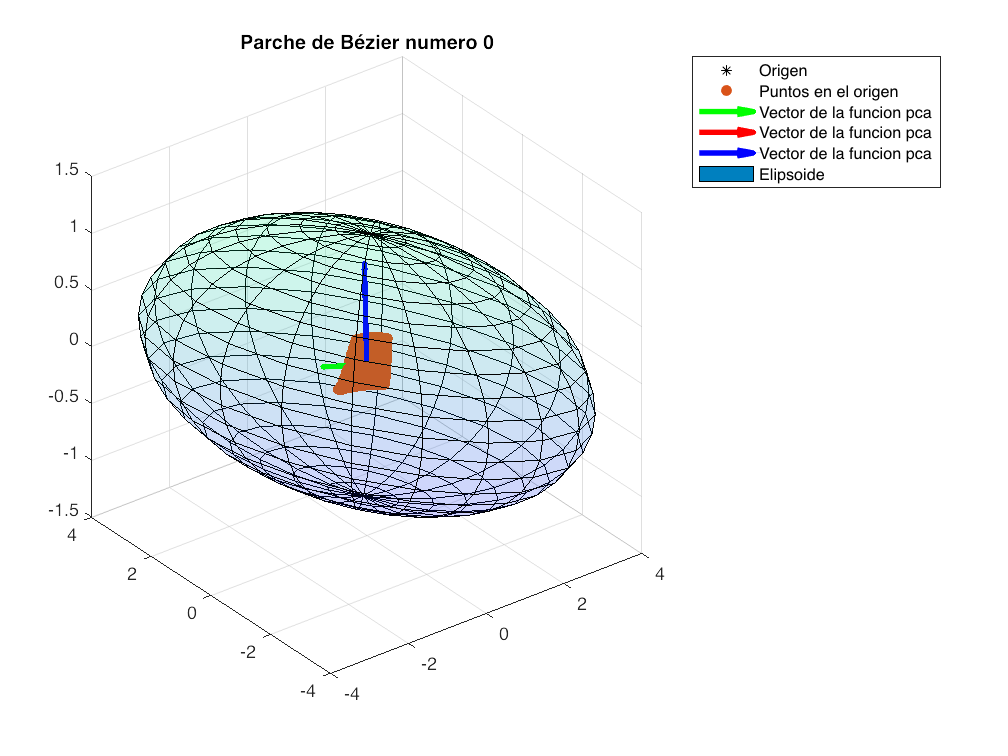


numero_puntos_u = 4;
numero_puntos_v = 7; 

grado_u = numero_puntos_u - 1; 
grado_v = numero_puntos_v - 1; 

matriz_elipsoide_parches = zeros(7*4,3); 

% Desde donde se va a iniciar a ver los parches 
ni = 0;

% Hasta donde se van a ver los parches 
% nf = (puntos - 1);
nf = 0;


for j = ni:nf
    for i = 1:numero_puntos_v
        Matriz_x(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),1,i);
        Matriz_y(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),2,i);
        Matriz_z(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),3,i);
    end
    
    
% Construcción de los parches de bezier   
    [vector_parche_bezier_x, vector_parche_bezier_y, vector_parche_bezier_z] = ParchesBezier(Matriz_x, Matriz_y, Matriz_z, grado_u, grado_v, false);

surf(Matriz_x,Matriz_y,Matriz_z)
hold on
surf(vector_parche_bezier_x,vector_parche_bezier_y,vector_parche_bezier_z)

    % Dibujo del origen 
    figure; 
    origen = [0 0 0];
    plot3(origen(1), origen(2),origen(3),'*k','DisplayName','Origen')
    name = 'Parche de Bézier numero ' + string(j);
    title(name);
    hold on
    grid on 
    
% Dibujo el parche de Bezier 
puntos_parche_x = vector_parche_bezier_x(:);
puntos_parche_y = vector_parche_bezier_y(:);
puntos_parche_z = vector_parche_bezier_z(:);

    for i = 0:6
    matriz_elipsoide_parches((1+4*i):(4*(1+i)),1) = Matriz_x(1+i,1:4);
    matriz_elipsoide_parches((1+4*i):(4*(1+i)),2) = Matriz_y(1+i,1:4);
    matriz_elipsoide_parches((1+4*i):(4*(1+i)),3) = Matriz_z(1+i,1:4);
    end   
    
    size(matriz_elipsoide_parches)
     
punto_medio_parche = mean(matriz_elipsoide_parches);

% Otro metedo para encontrar los vactores utilizando pca
xpca = puntos_parche_x;
ypca = puntos_parche_y;
zpca = puntos_parche_z;

[Upca, score, latent, tsquared, explained, mu] = pca([xpca,ypca,zpca])

%Calcular la nueva posición del parche, llevarlo al origen 
origen_puntoX = puntos_parche_x - punto_medio_parche(1);
origen_puntoY = puntos_parche_y - punto_medio_parche(2);
origen_puntoZ = puntos_parche_z - punto_medio_parche(3);

matriz_origen(:,1) = origen_puntoX;
matriz_origen(:,2) = origen_puntoY;
matriz_origen(:,3) = origen_puntoZ;

punto_medio_origen = mean(matriz_origen)

scatter3(origen_puntoX,origen_puntoY,origen_puntoZ,'filled','DisplayName','Puntos en el origen')

xpca_origen = origen_puntoX;
ypca_origen = origen_puntoY;
zpca_origen = origen_puntoZ;

Upca_origen = pca([xpca_origen,ypca_origen,zpca_origen]);

% Encontrar el vector ortonormal a los vectores del fitting 
fitting1 = [Upca_origen(1,1),Upca_origen(2,1),Upca_origen(3,1)];
fitting2 = [Upca_origen(1,2),Upca_origen(2,2),Upca_origen(3,2)];
fitting3 = cross(fitting1,fitting2);

%Despliegue de los vectores encontrados por la funcion pca
hold on
q1pca_origen = quiver3(punto_medio_origen(1),punto_medio_origen(2),punto_medio_origen(3),Upca_origen(1,2),Upca_origen(2,2),Upca_origen(3,2),'g','DisplayName','Vector de la funcion pca');
q2pca_origen = quiver3(punto_medio_origen(1),punto_medio_origen(2),punto_medio_origen(3),Upca_origen(1,1),Upca_origen(2,1),Upca_origen(3,1),'r','DisplayName','Vector de la funcion pca');
q1pca_origen.LineWidth = 3;
q2pca_origen.LineWidth = 3;
legend

hold on 
q3pca_origen = quiver3(punto_medio_origen(1),punto_medio_origen(2),punto_medio_origen(3),fitting3(1),fitting3(2),fitting3(3),'b','DisplayName','Vector de la funcion pca');
q3pca_origen.LineWidth = 3;

% Se va a generar la matriz para rotar los puntos del elipsoide para que
% coincidan 
matriz_rotacion = [fitting1' fitting2' fitting3']

% Verificación de que la matriz es una rotación. Si el determinante da 1 es
% una rotación si da -1 es una rotación con una reflexión. 
determinanate_matriz_rotacion = det(matriz_rotacion)


% Minimizar el volumen del elipsoide
% Ejes del elipsoide
a = mu(1);
b = mu(2); 
c = mu(3); 

% Creación del elipsoide, por medio de la funcion ellipsoid()
colormap winter
[Xp,Yp,Zp] = ellipsoid(punto_medio_origen(1), punto_medio_origen(2),punto_medio_origen(3), ...
   a,b,c);

% Rotación del elipsoide 
Xp1 = Xp(:);
Yp1 = Yp(:);
Zp1 = Zp(:);
matriz_elipsoide_origen = [Xp1 Yp1 Zp1];
max = length(matriz_elipsoide_origen);


for i = 1:max
    matriz_elipsoide_rotada(i,:) = matriz_elipsoide_origen(i,:) * matriz_rotacion;
end

Xp_rotada = [];
Yp_rotada = [];
Zp_rotada = [];

for i = 0:20
    for j = 1:21
        Xp_rotada(j,i+1) = matriz_elipsoide_rotada(j+(i*21),1);
        Yp_rotada(j,i+1) = matriz_elipsoide_rotada(j+(i*21),2);    
        Zp_rotada(j,i+1) = matriz_elipsoide_rotada(j+(i*21),3);
    end 
end 


hold on 
% Dibujar el elipsoide
surf(Xp_rotada,Yp_rotada,Zp_rotada,'FaceAlpha',0.1,'DisplayName','Elipsoide')
    
end